clear
clc

## Selecting the Waveform Files.

disp("Select the Median Elbow axoscope file!")

Select the Median Elbow axoscope file!


axoload

Filename: Z:\Backup DNS323 NAS\User Files S to Z\Simon Wu\Technique Paper\Axoscope Patient Data\Nov 12th, 2020\Mockford Wayne\Ulnar Wrist (hypothenar).abf
Comment: Ulnar Wrist (hypothenar) - Mockford Wayne               
Samp Rate(Hz): 5000.00	#Sweeps: 1
Col	Ch#	Units            	Ch.Name
  1	  1	(1/1000)xmV      	Hypothenar


ans = 	1.0e+03 *

    0.0209
    9.8953
   -0.0100
   -0.0350
   -0.0250
   -0.0300
   -0.0250
   -0.0150
   -0.0200
   -0.0200


selected = input('Were you able to select the appropriate file? Enter [y/n]','s')

selected = 'y'

me = ans / 1000;
while selected == "n"
    disp("Select the Median Elbow axoscope file!")
    axoload
    selected = input('Were you able to select the appropriate file? Enter [y/n]','s')
    if selected == "y"
        me = ans / 1000;

        continue 
    end
end

disp("Select the Median Wrist axoscope file!")

Select the Median Wrist axoscope file!


axoload

Filename: Z:\Backup DNS323 NAS\User Files S to Z\Simon Wu\Technique Paper\Axoscope Patient Data\Nov 12th, 2020\Mockford Wayne\Median Elbow (hypothenar) - MW.abf
Comment: Median Elbow (hypothenar) - Mockford Wayne              
Samp Rate(Hz): 5000.00	#Sweeps: 1
Col	Ch#	Units            	Ch.Name
  1	  1	(1/1000)xmV      	Hypothenar


ans = 	1.0e+03 *

    0.0209
    0.0400
   -0.0050
    0.0150
    0.0500
    0.0400
    0.0300
    0.0100
    0.0250
    0.0250


selected = input("Were you able to select the appropriate file? Enter [y/n]",'s')

selected = 'y'

mw = ans / 1000;
while selected =="n"
    disp("Select the Median Wrist axoscope file!")
    axoload
    selected = input("Were you able to select the appropriate file? Enter [y/n]",'s')
    if selected == "y"
        mw = ans / 1000;
        continue
    end
end

disp("Select the Ulnar Wrist axoscope file!")

Select the Ulnar Wrist axoscope file!


axoload

Filename: Z:\Backup DNS323 NAS\User Files S to Z\Simon Wu\Technique Paper\Axoscope Patient Data\Nov 12th, 2020\Mockford Wayne\Ulnar Wrist (hypothenar).abf
Comment: Ulnar Wrist (hypothenar) - Mockford Wayne               
Samp Rate(Hz): 5000.00	#Sweeps: 1
Col	Ch#	Units            	Ch.Name
  1	  1	(1/1000)xmV      	Hypothenar


ans = 	1.0e+03 *

    0.0209
    9.8953
   -0.0100
   -0.0350
   -0.0250
   -0.0300
   -0.0250
   -0.0150
   -0.0200
   -0.0200


selected = input("Were you able to select the appropriate file? Enter [y/n]",'s')

selected = 'y'

uw = ans / 1000;
while selected == "n"
    disp("Select the Ulnar Wrist file.")
    axoload
    selected = input("Were you able to select the appropriate file? Enter [y/n]",'s')
    if selected == "y"
        uw = ans / 1000;
        continue
    end
end

disp("Select the Ulnar Elbow axoscope file!")
axoload
selected = input("Were you able to select the appropriate file? Enter [y/n]",'s')
ue = ans / 1000;
while selected == "n"
    disp("Select the Ulnar Elbow file.")
    axoload
    selected = input("Were you able to select the appropriate file? Enter [y/n]",'s')
    if selected == "y"
        ue = ans / 1000;
        continue
    end
end

## Plotting Raw Waveforms and Determining Onset Points.

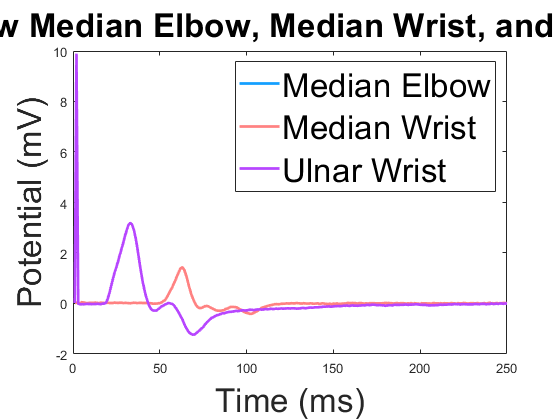

ome = 18

hold off
plot(me,'color','[0.0745 0.6235 1.0000]','LineWidth',2)
hold on
plot(mw,'color','[1.0000 0.5098 0.5098]','LineWidth',2)
hold on
plot(uw,'color','[0.7176 0.2745 1.0000]','LineWidth',2)

% legends & axes
lgd = legend('Median Elbow','Median Wrist','Ulnar Wrist');
lgd.FontSize = 25;

lgd = title('Plot of Raw Median Elbow, Median Wrist, and Ulnar Wrist');
lgd.FontSize = 25;

lgd = xlabel('Time (ms)');
lgd.FontSize = 25;
lgd = ylabel('Potential (mV)');
lgd.FontSize = 25;

ome = input('Please enter the onset point of the Median Elbow waveform (blue) --->')

selected = input("Are you happy with the onset point you have selected? Enter [y/n]",'s')

selected = 'y'

while selected =="n"
    ome = input('Please enter the onset point of the Median Elbow waveform (blue) --->')
    selected = input("Are you happy with the onset point you have selected? Enter [y/n]",'s')
    if selected == "y"
        continue
    end
end

omw = input('Please enter the onset point of the Median Wrist waveform (red) --->')

omw = 46

selected = input("Are you happy with the onset point you have selected? Enter [y/n]",'s')

selected = 'y'

while selected =="n"
    omw = input('Please enter the onset point of the Median Wrist waveform (red) --->')
    selected = input("Are you happy with the onset point you have selected? Enter [y/n]",'s')
    if selected == "y"
        continue
    end
end

ouw = input('Please enter the onset point of the Ulnar Wrist waveform (purple) --->')

ouw = 18

selected = input("Are you happy with the onset point you have selected? Enter [y/n]",'s')

selected = 'y'

while selected =="n"
    ouw = input('Please enter the onset point of the Ulnar Wrist waveform (purple) --->')
    selected = input("Are you happy with the onset point you have selected? Enter [y/n]",'s')
    if selected == "y"
        continue
    end
end


## Plotting Shifted Waveforms and Median Elbow-Median Wrist Subtracted Waveform.

hold off

sme = me(ome:end); % Adding "s" = shifted
[sizeSME,valueME] = size(me);

smw = mw(omw:(sizeSME - ome + omw));

Index exceeds the number of array elements (250).

suw = uw(ouw:(sizeSME - ome + ouw));

a = sme - smw;

hold off
figure(1);
plot(sme,'color',[0.0039 0.5098 0.7059],'LineWidth',2)
hold on
plot(smw,'color','r','LineWidth',2)
plot(a,'color','[0.3216    0.9804    0.5961]','LineWidth',2)

% legends & axes
lgd = legend('Median Elbow','Median Wrist','Ulnar Wrist');
lgd.FontSize = 25;

lgd = title('Plot of Shifted Median Elbow, Median Wrist, and Ulnar Wrist');
lgd.FontSize = 25;

lgd = xlabel('Time (ms)');
lgd.FontSize = 25;
lgd = ylabel('Potential (mV)');
lgd.FontSize = 25;

## Analyzing Negative Peak Amplitude and Area; Compared to Ulnar Wrist.

% 1. Plot of Median Elbow & Median Wrist.
figure(2);
subplot(3,1,1)
plot(sme,'color',[0.0039 0.5098 0.7059],'LineWidth',2)
hold on
plot(smw,'color','r','LineWidth',2)

ylim([-3 8]);

% create visible x-axis line
area(0)

% legends & axes for first plot
lgd = legend('Median Wrist','Median Elbow');
lgd.FontSize = 25;

lgd = title('Plot of Median Elbow and Median Wrist');
lgd.FontSize = 25;

lgd = xlabel('Time (ms)');
lgd.FontSize = 25;
lgd = ylabel('Potential (mV)');
lgd.FontSize = 25;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2. Plot of Subtracted Waveform.
subplot(3,1,2)
plot(a,'color','[0.3216    0.9804    0.5961]','LineWidth',2)%%% outline of area

ylim([-3 8]);

hold on
trapz(a) %%% numeric value of area

plot(NaN,'om') %%% colour of median amplitude

area(a,'FaceColor','[0.3216    0.9804    0.5961]') %%% colour of area of difference

% legends & axes for 2nd plot
lgd = legend(sprintf('Negative Peak Area = %f',trapz(a)),sprintf('Negative Peak Amplitude = %f',abs(max(a))));
lgd.FontSize = 25;
%(-min(p))

lgd = title('Difference Between Median Elbow and Median Wrist');
lgd.FontSize = 25;

lgd = xlabel('Time (ms)');
lgd.FontSize = 25;
lgd = ylabel('Potential (mV)');
lgd.FontSize = 25;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 3. Plot of Ulnar Wrist Waveform.
subplot(3,1,3)
plot(suw, 'color', '[0.7176 0.2745 1.0000]', 'LineWidth',2)

ylim([-3 8]);

hold on
plot(NaN,'og') %%% colour of ulnar amplitude
area(0)

% legends & axes for 3rd plot
lgd = legend(sprintf('Ulnar Wrist Reference Negative Peak Amplitude = %f',abs(max(suw))));
lgd.FontSize = 25;

lgd = title('Plot of Ulnar Wrist');
lgd.FontSize = 25;

lgd = xlabel('Time (ms)');
lgd.FontSize = 25;
lgd = ylabel('Potential (mV)');
lgd.FontSize = 25;